## **Live Script for Testing Various Filtering Methods**

The following script has been designed to add and compare different types of ftilers against one another. The script allows for dynamic adjustment of variables such as smoothing factors.

### Data Ingestion

clear
addpath('Data Processing Functions')

The first thing the script needs to do is load in an example dataset. Use the below text

file_location = "Matlab App Data Tables/Left Arm/Motion 1/Matt_Motion1_7";
imu_data = load('-mat',file_location).saved_table;
imu_data = AddTimeToIMUData(imu_data);
head(imu_data,5)

ans = 5×32 table
    timestamp       time      accelX_1    accelY_1    accelZ_1    gyroX_1    gyroY_1    gyroZ_1    magX_1    magY_1    magZ_1    accelX_2    accelY_2    accelZ_2    gyroX_2    gyroY_2    gyroZ_2    magX_2     magY_2    magZ_2    accelX_3    accelY_3    accelZ_3    gyroX_3    gyroY_3    gyroZ_3    magX_3     magY_3    magZ_3     movement_smoothness    movement_completeness    movement_type
    __________    ____

#### Choosing a Feature

Use the below drop down to choose which feature from the table will be filtered and plotted onto the graphs.

feature_to_use = "accelZ_3";
table_index = find(imu_data.Properties.VariableNames == feature_to_use);
data_units = imu_data.Properties.VariableUnits{table_index};

data_to_use = imu_data.(feature_to_use);
time_to_use = imu_data.('time');
%% clear table_index imu_data

### Filtering

#### [lowpass(x,wpass)](https://www.mathworks.com/help/signal/ref/lowpass.html)

    Lowpass is a built-in function to matlab and takes a array and filters it based on a value of 'wpass'. Use the below slider to set a value for 'wpass'. 

lowpass_wpass =0.15;
tic
filtered_lowpass = lowpass(data_to_use,lowpass_wpass);
lowpass_time = toc;

#### [smoothdata(x,smoothing_type)](https://www.mathworks.com/help/matlab/ref/smoothdata.html)

    Smoothdata is a built-in function to matlab and takes a array and filters it based on a an option of two things.

- *   Moving Window (A time delta to calculate between)*

-    *Smoothing Factor (Any value between 0 and 1).*

    Use the below drop down to choose with smoothing function you'd like to use

smooth_method ="MovingWindow";

    Use the below slider to change the smoothing factor.

***    This slider will only work if 'Smoothing Factor' has been selected!***

smoothing_factor =0.2;

    Use the below slider to change the moving window.

***    This slider will only work if 'Moving Window' has been selected!***

moving_window_size =400;

smooth_plot_title_extra = "";

switch smooth_method
    case "SmoothingFactor"
        smooth_plot_title_extra = " Smoothing = " + string(smoothing_factor);
        
        tic
        filtered_smooth_gaussian = smoothdata(data_to_use,'gaussian','SmoothingFactor',smoothing_factor,...
            'SamplePoints',time_to_use);
        smooth_gaussian_time = toc;
        
        tic
        filtered_smooth_movmean = smoothdata(data_to_use,'movmean','SmoothingFactor',smoothing_factor,...
            'SamplePoints',time_to_use);
        smooth_movmean_time = toc;
        
        tic
        filtered_smooth_movmedian = smoothdata(data_to_use,'movmedian','SmoothingFactor',smoothing_factor,...
            'SamplePoints',time_to_use);
        smooth_movmedian_time = toc;
        
        tic
        filtered_smooth_lowess = smoothdata(data_to_use,'lowess','SmoothingFactor',smoothing_factor,...
            'SamplePoints',time_to_use);
        smooth_lowess_time = toc;

        tic
        filtered_smooth_rlowess = smoothdata(data_to_use,'rlowess','SmoothingFactor',smoothing_factor,...
            'SamplePoints',time_to_use);
        smooth_rlowess_time = toc;

        tic
        filtered_smooth_loess = smoothdata(data_to_use,'loess','SmoothingFactor',smoothing_factor,...
            'SamplePoints',time_to_use);
        smooth_loess_time = toc;

        tic
        filtered_smooth_rloess = smoothdata(data_to_use,'rloess','SmoothingFactor',smoothing_factor,...
            'SamplePoints',time_to_use);
        smooth_rloess_time = toc;
        
        tic
        filtered_smooth_sgolay = smoothdata(data_to_use,'sgolay','SmoothingFactor',smoothing_factor,...
            'SamplePoints',time_to_use);
        smooth_sgolay_time = toc;
        
    case "MovingWindow"
        smooth_plot_title_extra = " Window = " + string(moving_window_size) + "ms";
        
        tic
        filtered_smooth_gaussian = smoothdata(data_to_use,'gaussian',milliseconds(moving_window_size),...
            'SamplePoints',time_to_use);
        smooth_gaussian_time = toc;
        
        tic
        filtered_smooth_movmean = smoothdata(data_to_use,'movmean',milliseconds(moving_window_size),...
            'SamplePoints',time_to_use);
        smooth_movmean_time = toc;
        
        tic
        filtered_smooth_movmedian = smoothdata(data_to_use,'movmedian',milliseconds(moving_window_size),...
            'SamplePoints',time_to_use);
        smooth_movmedian_time = toc;
        
        tic
        filtered_smooth_lowess = smoothdata(data_to_use,'lowess',milliseconds(moving_window_size),...
            'SamplePoints',time_to_use);
        smooth_lowess_time = toc;

        tic
        filtered_smooth_rlowess = smoothdata(data_to_use,'rlowess',milliseconds(moving_window_size),...
            'SamplePoints',time_to_use);
        smooth_rlowess_time = toc;

        tic
        filtered_smooth_loess = smoothdata(data_to_use,'loess',milliseconds(moving_window_size),...
            'SamplePoints',time_to_use);
        smooth_loess_time = toc;

        tic
        filtered_smooth_rloess = smoothdata(data_to_use,'rloess',milliseconds(moving_window_size),...
            'SamplePoints',time_to_use);
        smooth_rloess_time = toc;
        
        tic
        filtered_smooth_sgolay = smoothdata(data_to_use,'sgolay',milliseconds(moving_window_size),...
            'SamplePoints',time_to_use);
        smooth_sgolay_time = toc;
end

#### Butterworth Filter

butter_order = 6;
butter_fs = 20;
butter_fc = 2.5;

array_order_prefix = ["st", "nd", "rd"];
butter_order_prefix = "";

if butter_order > length(array_order_prefix)
    butter_order_prefix = "th";
else
    butter_order_prefix = array_order_prefix(butter_order);
end

butter_filter = ButterLowpass(butter_order,butter_fs,butter_fc);
tic
filtered_butterworth_lowpass = filter(butter_filter,data_to_use);
butterworth_time = toc;

### Filtering Plots

raw_data_color = [109 185 226 120]/255;
filtered_data_color = [0 100 0 150]/255;

raw_line_width = 1;
filtered_line_width = 1.5;

Below is a group of plots showing how the filters have plotted the same set of data. The lighter color shows the raw/unfiltered data and the darker/vibrant color shows the filtered data. The title for each graph shows the function that was used for that plot. Adjusting the above sliders will adjust these plots so play around with any of the values to find a favourite. 

The title for the grouped plots will display a string with a "...gyroY_3". This is to show that the data that was filtered was the Y gyro from IMU 3. 

Use the below check box if you want to plot the graph in an external window.

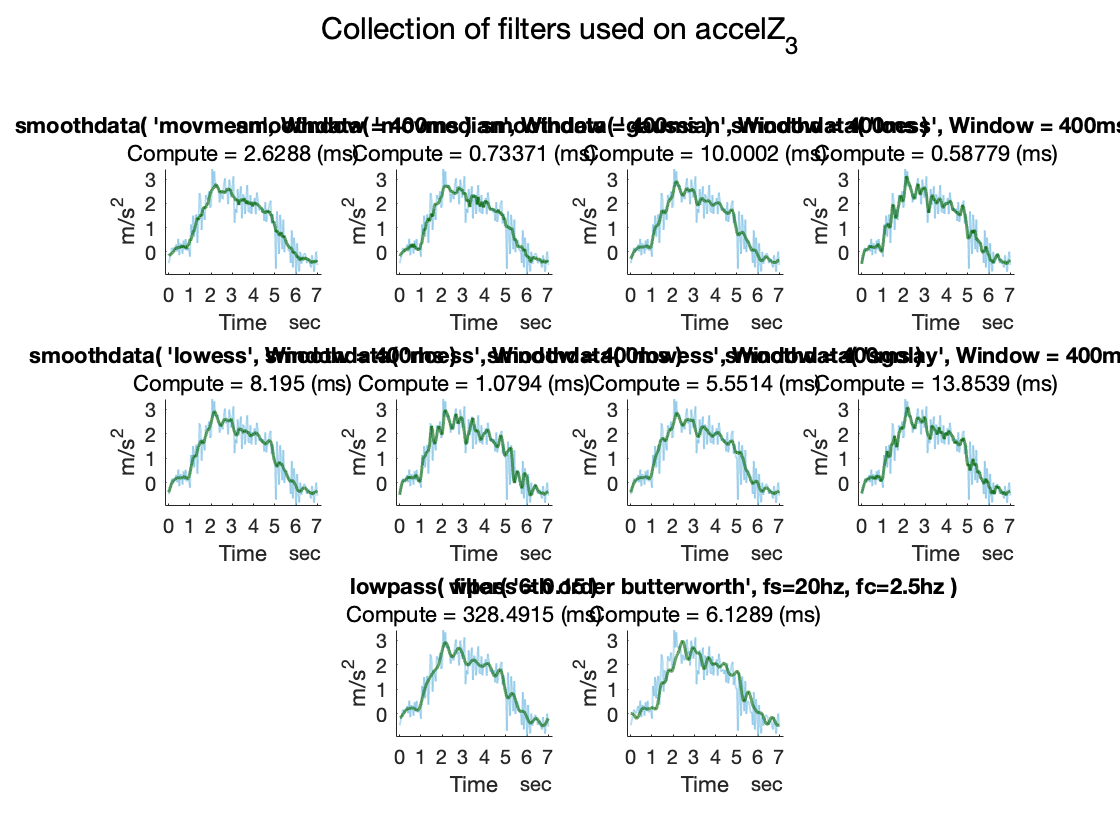

plot_chart_in_window = true;
clf;
figure(1);

switch plot_chart_in_window
    case true
        set(gcf, 'Visible', true ,'Color', [1,1,1]);
    case false
        set(gcf, 'Color', [1,1,1]);
end

subplot(3,4,1)
hold on
plot(time_to_use, data_to_use, "Color", raw_data_color, "LineWidth", raw_line_width);
plot(time_to_use, filtered_smooth_movmean, "Color", filtered_data_color, "LineWidth", filtered_line_width);
title("smoothdata( 'movmean'," + string(smooth_plot_title_extra) + " )");
subtitle('Compute = ' + string(smooth_movmean_time*1000) + (' (ms)'));
xlabel('Time');
ylabel(data_units);
hold off

subplot(3,4,2)
hold on
plot(time_to_use, data_to_use, "Color", raw_data_color, "LineWidth", raw_line_width);
plot(time_to_use, filtered_smooth_movmedian, "Color", filtered_data_color, "LineWidth", filtered_line_width);
title("smoothdata( 'movmedian'," + string(smooth_plot_title_extra) + " )");
subtitle('Compute = ' + string(smooth_movmedian_time*1000) + (' (ms)'));
xlabel('Time');
ylabel(data_units);
hold off

subplot(3,4,3)
hold on
plot(time_to_use, data_to_use, "Color", raw_data_color, "LineWidth", raw_line_width);
plot(time_to_use, filtered_smooth_gaussian, "Color", filtered_data_color, "LineWidth", filtered_line_width);
title("smoothdata( 'gaussian'," + string(smooth_plot_title_extra) + " )");
subtitle('Compute = ' + string(smooth_gaussian_time*1000) + (' (ms)'));
xlabel('Time');
ylabel(data_units);
hold off

subplot(3,4,4)
hold on
plot(time_to_use, data_to_use, "Color", raw_data_color, "LineWidth", raw_line_width);
plot(time_to_use, filtered_smooth_loess, "Color", filtered_data_color, "LineWidth", filtered_line_width);
title("smoothdata( 'loess'," + string(smooth_plot_title_extra) + " )");
subtitle('Compute = ' + string(smooth_loess_time*1000) + (' (ms)'));
xlabel('Time');
ylabel(data_units);
hold off

subplot(3,4,5)
hold on
plot(time_to_use, data_to_use, "Color", raw_data_color, "LineWidth", raw_line_width);
plot(time_to_use, filtered_smooth_lowess, "Color", filtered_data_color, "LineWidth", filtered_line_width);
title("smoothdata( 'lowess'," + string(smooth_plot_title_extra) + " )");
subtitle('Compute = ' + string(smooth_lowess_time*1000) + (' (ms)'));
xlabel('Time');
ylabel(data_units);
hold off

subplot(3,4,6)
hold on
plot(time_to_use, data_to_use, "Color", raw_data_color, "LineWidth", raw_line_width);
plot(time_to_use, filtered_smooth_rloess, "Color", filtered_data_color, "LineWidth", filtered_line_width);
title("smoothdata( 'rloess'," + string(smooth_plot_title_extra) + " )");
subtitle('Compute = ' + string(smooth_rloess_time*1000) + (' (ms)'));
xlabel('Time');
ylabel(data_units);
hold off

subplot(3,4,7)
hold on
plot(time_to_use, data_to_use, "Color", raw_data_color, "LineWidth", raw_line_width);
plot(time_to_use, filtered_smooth_rlowess, "Color", filtered_data_color, "LineWidth", filtered_line_width);
title("smoothdata( 'rlowess'," + string(smooth_plot_title_extra) + " )");
subtitle('Compute = ' + string(smooth_rlowess_time*1000) + (' (ms)'));
xlabel('Time');
ylabel(data_units);
hold off

subplot(3,4,8)
hold on
plot(time_to_use, data_to_use, "Color", raw_data_color, "LineWidth", raw_line_width);
plot(time_to_use, filtered_smooth_sgolay, "Color", filtered_data_color, "LineWidth", filtered_line_width);
title("smoothdata( 'sgolay'," + string(smooth_plot_title_extra) + " )");
subtitle('Compute = ' + string(smooth_sgolay_time*1000) + (' (ms)'));
xlabel('Time');
ylabel(data_units);
hold off

subplot(3,4,10)
hold on
plot(time_to_use, data_to_use, "Color", raw_data_color, "LineWidth", raw_line_width);
plot(time_to_use, filtered_lowpass, "Color", filtered_data_color, "LineWidth", filtered_line_width);
title('lowpass( wpass = ' + string(lowpass_wpass) + ' )');
subtitle('Compute = ' + string(lowpass_time*1000) + (' (ms)'));
xlabel('Time');
ylabel(data_units);
hold off

subplot(3,4,11)
hold on
plot(time_to_use, data_to_use, "Color", raw_data_color, "LineWidth", raw_line_width);
plot(time_to_use, filtered_butterworth_lowpass, "Color", filtered_data_color, "LineWidth", filtered_line_width);
title("filter( '" + string(butter_order) + string(butter_order_prefix) + " order butterworth', fs=" + string(butter_fs) + "hz, fc=" + string(butter_fc) + "hz )");
subtitle('Compute = ' + string(butterworth_time*1000) + (' (ms)'));
xlabel('Time');
ylabel(data_units);
hold off

sgtitle('Collection of filters used on ' + string(feature_to_use));


drawnow;